%Q1 V={ v € H1, v=0 sur la frontière de Dirichlet}
% est l'espace de Hilbert utilisé pour écrire la formulation
% variationelle du problème.

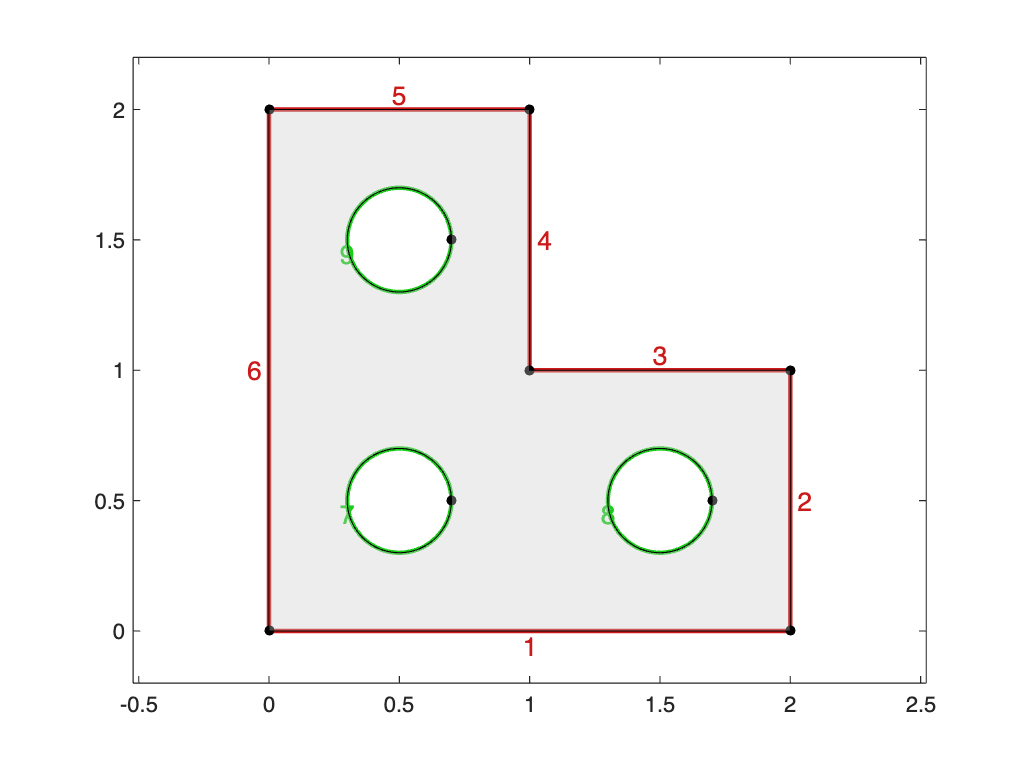

%Q2 Définition du maillage

nodes = [0 0 ; 2 0 ; 2 1 ; 1 1 ; 1 2 ; 0 2 ; .7 .5 ; 1.7 .5 ; .7 1.5];
edges = {{1 ,2} ,{2 ,3} ,{3 ,4} ,{4 ,5} ,{5 ,6} ,{6 ,1} ,...
{7 ,7 ,' 0.5+0.2* cos( t )',' 0.5+0.2* sin( t )' ,[0 ,2*pi ] ,'r'} ,...
{8 ,8 ,' 1.5+0.2* cos( t )',' 0.5+0.2* sin( t )' ,[0 ,2*pi ] ,'r'} ,...
{9 ,9 ,' 0.5+0.2* cos( t )',' 1.5+0.2* sin( t )' ,[0 ,2*pi ] ,'r'}};
domain = Domain( nodes , edges ) ;
domain.plot ('edgelabels') ;

h = 0.1;
mesh = Mesh( domain ,h , h/5) ;

building mesh
- basic properties
- P1 basis
- stiffness and mass matrices
- differential matrices
done (5117 triangles, 0.8 s)


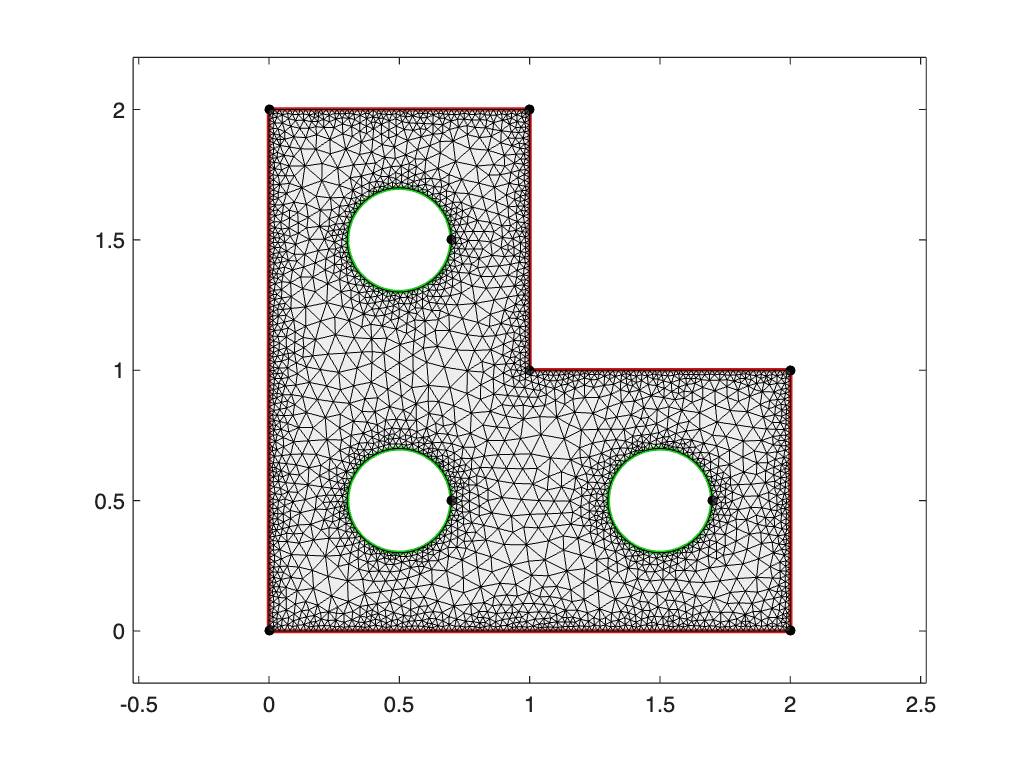

mesh.plot ;

%Q3 
E = mesh.boundary_edges(:,1:2);